# **Create a massspectrum and define ranges**

This Livescript will guid you through the first steps of the reconstruction of an Atom-Probe-Dataset with this toolbox.

First of all you have to load some basics as the clolorScheme which provides color for all elements of the periodic table. In isotopeTable_naturalAbundances all isotopes of the elements there weight, abundance and atomDensity are given. After this you can load your *.pos file. An window will pop-up and you can choose your file. If you have an *.epos file be aware you change your selection window on *.epos. 

load isotopeTable_naturalAbundances.mat
load colorScheme.mat
pos = posToTable;

file R56_01769-v01.pos loaded


When the pos file is loaded you can plot your massspectrum. You can change the step width and the plotting mode as seen in the code. A mode is 'count' which only shows the number of counts above the mass-to-charge ratio the other is 'normalized' which shows number of the counts per Dalton over total counts.

bin = 0.1% Width of the steps in which the plot is performed

bin = 0.1000

mode = 'normalised' % Specifies the way the counts are applied

mode = 'normalised'

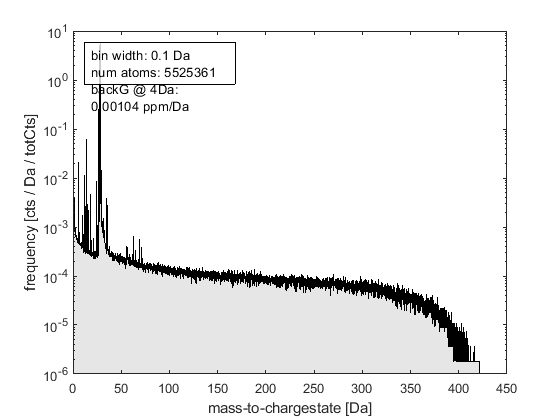

Error using matlab.graphics.interaction.webmodes.toggleMode
Unknown action character vector.

Error in matlab.graphics.interaction.webmodes.modeHelper

Error in matlab.graphics.interaction.webmodes.modeFunctionHelper

Error in matlab.graphics.interaction.webmodes.panWeb

Error in pan (line 206)
            matlab.graphics.interaction.webmodes.panWeb(arg1, []);

Error in massSpecPlot (

spec = massSpecPlot(pos,bin,mode); % Plots your massspectrum

After you plotted your massspectrum you can now range your dataset in two ways.

## Adding ions with knownledge of occurring ions

To add an know ion to your massspectrum you only need to use the ionAdd function. Therefore you first parse the massspectrum in which the range should be plotted. After this you enter the name of your ion, the chargestate of the ion which can be an vector. You also have to enter the margin within which two peaks will be summed up, the minimal abundance, the height of the most abundant isotope, which can be choosen as 'selection' and 'most abundat', and the maximal seperation of two peaks.

ion = 'Fe' % chemical symbol of the ion that will be added

ion = 'Fe'

chargeState = 2 % charge state of the ion, vector of charge states

chargeState = 2

sumMargin = 0.15 % specifies a margin within which two peaks will be summed up

sumMargin = 0.1500

minAbundance = 0.43 % is the minimal abundance

minAbundance = 0.4300

maxHeight = 'selection' % is the height of the most abundant isotope

maxHeight = 'selection'

maxSeparation = 0.2 % the maximum of the mass spectrum within this range will be used for scaling

maxSeparation = 0.2000


ionAdd(spec,ion,chargeState,isotopeTable,colorScheme,sumMargin,minAbundance,maxHeight,maxSeparation) % ionAdd creates a stem plot in the mass spectrum (spec) for the parsed ion and its corresponding charge state

Unrecognized function or variable 'spec'.

## Adding ions without knowledge of occurring ions

To add an unknown ion to your massspectrum ionFind will be the right choice. To execute this function you first have to create an ionTable which contains all possible ions.

element = '' % can be a list of atomic numbers, symbols or 'all'
chargeStates = 2 % list of chargeStates
maxComplexity = 2 %  maximal complexity of the created ions
complexFormers = '' %  if complexformers = 'std' complexformers = H, H2, H3, He, B, C, C2, C3, N, O, O2. If complexFormers = 'and C P ....' it takes the elements in elements and adds the additional specified elements
abundanceThreshold = 0.001 % sets an threshold for used isotopes to build the
%                       list
ionTable = ionsTableCreate(elements,chargeStates,maxComplexity,complexFormers,abundanceThreshold,isotopeTable)

.